## Question 1

We begin by writing a script that uses a *for* loop to generate the value of $\pi$. 

clear

% This gives us a table of random points, correspondent to the number of
% points we want to generate. Additionally, we create a vector of the
% distance of points from (0.5, 0.5), and a vector for the iterated values
% of pi
numPoints = 100000;
genPoints = [rand(numPoints, 2)]; 

distPoints = zeros(numPoints,1);
iterPi = zeros(numPoints,1);

% Our for loop calculates the iterates of our Monte Carlo simulation for
% plotting convergence. This can alternatively be done with vectorized
% operations, eliminating the need for a for loop
for i = 1:numPoints
    distPoints(i) = dist(genPoints(i,:));
    iterPi(i) = calcPi(distPoints(1:i), i);
end

% Here, we display the approximate value of pi
fprintf('Approximate value of pi: %.15f\n', iterPi(end));

Approximate value of pi: 3.147240000000000


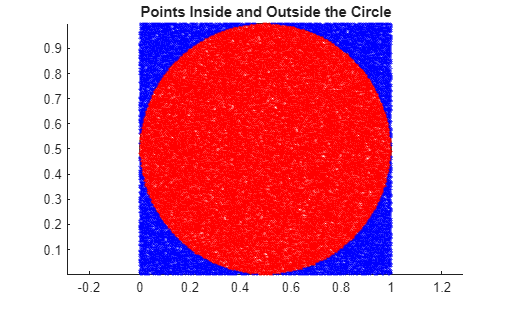


% We would now like to plot the circle and points
theta = linspace(0,pi*2, 100);
xCircle = 0.5 + 0.5*cos(theta);
yCircle = 0.5 + 0.5*sin(theta);
% Now plot the circle and the generated points
figure;
hold on;
fill(xCircle, yCircle, 'white', 'FaceAlpha', 0.9); % Circle
scatter(genPoints(distPoints <= 0.5, 1), genPoints(distPoints <= 0.5, 2), 1, 'r'); % Points inside the circle
scatter(genPoints(distPoints > 0.5, 1), genPoints(distPoints > 0.5, 2), 1, 'b'); % Points outside the circle
axis equal;
title('Points Inside and Outside the Circle');
hold off;

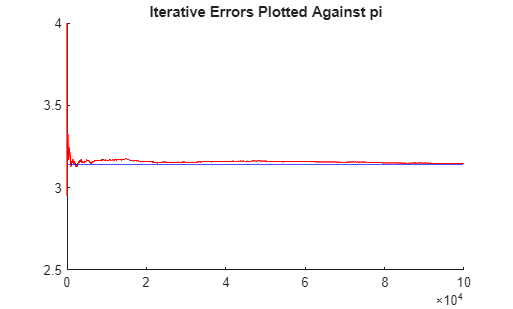


% Plotting iterative errors
figure;
hold on;
plot(1:numPoints, iterPi, 'red');
yline(pi,'blue');
ylim([2.5 4]);
title('Iterative Errors Plotted Against pi')
hold off;

Required Functions

% We write a function to determine which points are in the circle and
% additionally calculate the approximate value of pi.
function approxPi = calcPi(d,n)
    insideCircle = nnz(d(:) <= 0.5);
    % display(insideCircle)
    approxPi = (insideCircle / n) * 4;
end

% The distance function under the l^2 norm
function d = dist(v)
    d = abs(sqrt(sum((v-0.5).^2,2)));
end

A function version of the for loop is written below, without comments. This is specifically for precision vs time analysis.

% Precision vs cost analysis

% The point list represents the entries for numPoints that we use.
% The results matrix stores the approximate value of pi and the elapsed
% time.
pointList = [100, 1000, 10000, 50000, 100000, 250000];
results = zeros(length(pointList), 2);

% Our for loop loops through every value in the point list, evaluating the
% function for each entry.
for i = 1:length(pointList)
    numPoints = pointList(i);

    [approxPi, elapsedTime] = monteCarloPiAnalysis(numPoints);
    
    results(i, 1) = approxPi;
    results(i, 2) = elapsedTime;
    
    % We have a progress display to ensure our code is running
    fprintf('Completed analysis for %d points.\n', numPoints);
end

Completed analysis for 100 points.
Completed analysis for 1000 points.
Completed analysis for 10000 points.
Completed analysis for 50000 points.
Completed analysis for 100000 points.
Completed analysis for 250000 points.


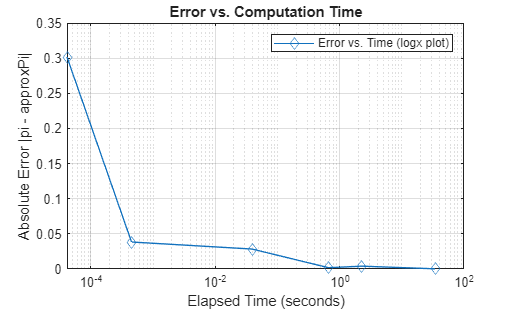


% This calculus the absolute error against pi
absError = abs(pi-results(:,1));

% Plotting iterative errors against computational time
figure;
semilogx(results(:, 2), absError, '-d');
grid on;
title('Error vs. Computation Time');
xlabel('Elapsed Time (seconds)');
ylabel('Absolute Error |pi - approxPi|');
legend('Error vs. Time (logx plot)');



% Function begins here
function [approxPi, elapsedTime] = monteCarloPiAnalysis(numPoints)
    startTime = tic;
    genPoints = rand(numPoints, 2);
    distPoints = zeros(numPoints, 1);
    iterPi = zeros(numPoints, 1);

    for i = 1:numPoints
        distPoints(i) = sqrt((genPoints(i,1) - 0.5)^2 + (genPoints(i,2) - 0.5)^2);
        pointsInside = sum(distPoints(1:i) <= 0.5);
        iterPi(i) = 4 * pointsInside / i;
    end

    approxPi = iterPi(end);
    elapsedTime = toc(startTime);
end

Now with matrix operations exclusively:

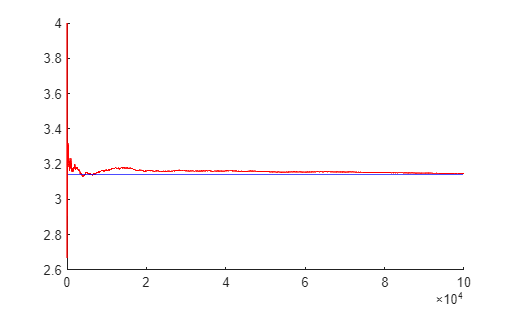

numPoints = 100000;
genPoints = [rand(numPoints, 2)]; 

distPoints = sqrt(sum((genPoints-0.5).^2,2));
insideCircle = nnz(distPoints(:) <= 0.5);

approxPi = (insideCircle / numPoints) * 4;

pointIndices = (1:numPoints)';
cumulativeInside = cumsum(distPoints(:)<= 0.5);
iterPi = (cumulativeInside ./ pointIndices) * 4;

figure;
hold on;
plot(pointIndices,iterPi,'red');
yline(pi, 'blue');
hold off


fprintf('Approximate value of pi: %.15f\n', approxPi);

Approximate value of pi: 3.146360000000000


## Question 2

In the following section, we adopt the above script to use a while loop to achieve a desired level of precision

clear

% Initial assumptions needed to bootstrap the while loop
batchSize = 500;
totalPoints = 0;
totalInside = 0;
tolerance = 0.001;
piCurrent = 10;
piPrevious = 0;
numIter = 0;


while abs(piCurrent - piPrevious) > tolerance
    piPrevious = piCurrent;

    % This generates a new list of points every iteration to check distance on
    newPoints = rand(batchSize, 2);
    % Checking distance of our list of points
    insideCircle = nnz(dist(newPoints) <= 0.5);

    % We count the number of totalPoints
    totalPoints = totalPoints + size(newPoints,1);
    % We count the number of inside points with totalInside
    totalInside = totalInside + insideCircle;
    piCurrent = (totalInside/totalPoints) * 4;

    % Iteration counter
    numIter = numIter + 1;
end


display(piCurrent);

piCurrent = 3.1328

display(totalPoints);

totalPoints = 2500

We are now asked to turn it into a function that takes user input for a certain *tolerance*. Precision as defined by convergence to pi is hard to define without more advanced statistical methods.

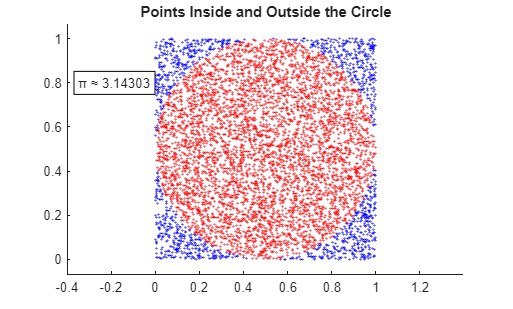

ans = 3.1430

% User defined precision for pi
function desiredPi = calcPiTol(precision)
    % Bootstrapping variables
    batchSize = 200;
    totalPoints = 0;
    totalInside = 0;
    piCurrent = 10;
    piPrevious = 0;
    numIter = 0;

    figure;
    
    % Filler needed for updating text on plot
    updateText = text(-0.35, 0.8, '0', 'EdgeColor', 'black');
    while abs(piCurrent - piPrevious) > precision
        piPrevious = piCurrent;
        % This generates a new list of points every iteration to check distance on
        newPoints = rand(batchSize, 2); 
        % Checking distance of our list of points
        insideCircle = nnz(dist(newPoints) <= 0.5);
    
        % We count the number of totalPoints
        totalPoints = totalPoints + size(newPoints,1);
        % We count the number of inside points with totalInside
        totalInside = totalInside + insideCircle;
        piCurrent = (totalInside/totalPoints) * 4;
        
        % Drawing figure
        hold on;
        xlim([-0.4, 1.4])
        scatter(newPoints(dist(newPoints) <= 0.5, 1), newPoints(dist(newPoints) <= 0.5, 2), 1, 'r'); % Points inside the circle
        scatter(newPoints(dist(newPoints) > 0.5, 1), newPoints(dist(newPoints) > 0.5, 2), 1, 'b'); % Points outside the circle
        axis equal;
        title('Points Inside and Outside the Circle');
        drawnow;
        piString = sprintf('π ≈ %.5f', piCurrent);
        set(updateText, 'String', piString);
        hold off;

        % Iteration counter
        numIter = numIter + 1;

        pause(0.25)
    end
    desiredPi = piCurrent;
end

calcPiTol(0.0001)